### Systemic Arteries Model (triangle wave for Qao)

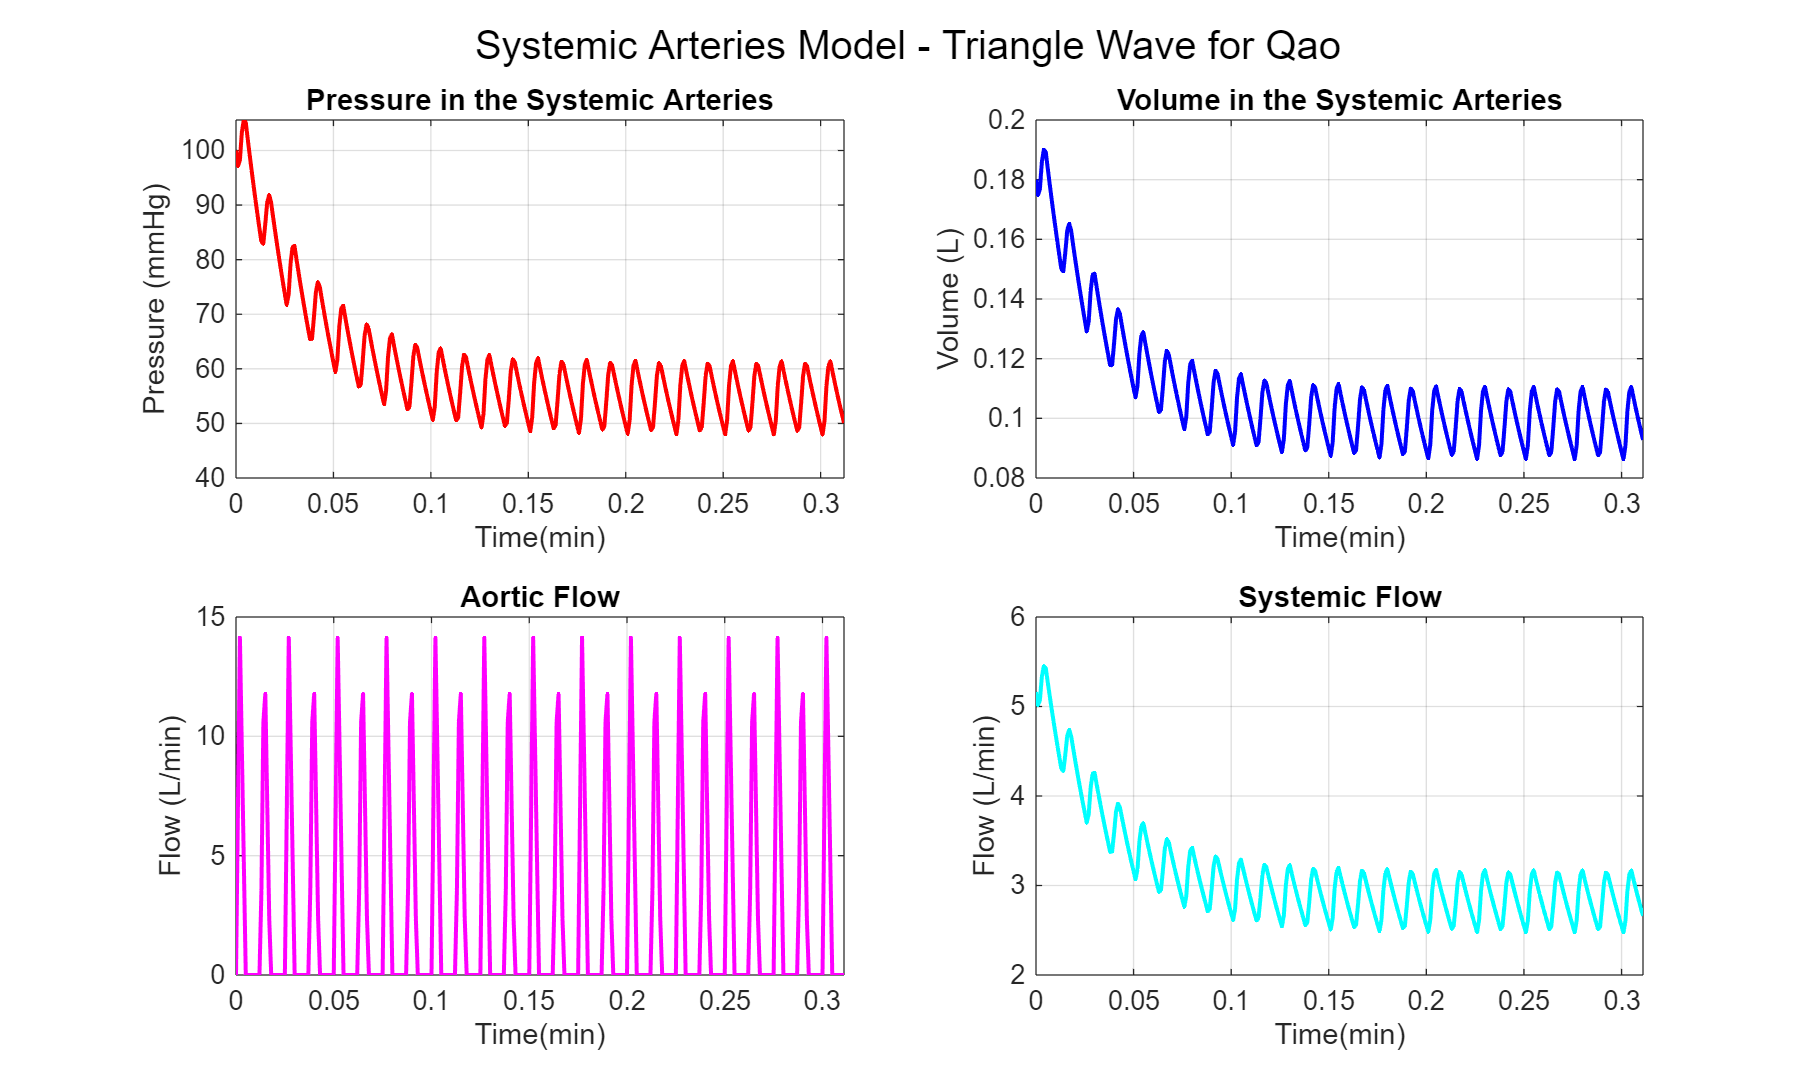

clear;clc;close all 

function Q=Qtriangwave(t,Qmax,T,ts,tmax)
% Find remainder of time between one heartbeat (T) and current time (t)
t1=rem(t,T);
    for ii=1:length(t)
        if t1(ii)<=ts % If remainder less than ts, heart is contracting
            if t1(ii)<=tmax % If remainder less than tmax heart is approaching max flow rate
                Q(ii)=Qmax*t1(ii)/tmax;
            else % If remainder greater than tmax but less than ts heart is reducing flow rate
                Q(ii)=Qmax*(ts-t1(ii))/(ts-tmax);
            end
        else % If remainder is not less than ts heart is in diastole, no flow
            Q(ii)=0;
        end
    end
end 

% Initial Parameters + Preallocating

T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 10e-4; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 

Rs  = 17.5*1.107; % Resistance of the systemic circuit (mmHg/(L/min)) 
Qmax=14.14; % Max flow rate through aorta during systole (L/min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 
% Csa & Rs were fiddled with to achieve Psa of 120/80 mmHg 

Psa=zeros(length(t),1); Psa(1)=100; % Pressure in systemic arteries (mmHg)
Vsa=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

for k=1:length(t)-1 
    Qao(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Aortic Flow 
    Qs(k)=Psa(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa(k+1)=Psa(k)+dt*(Qao(k)-Qs(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa(k)=Csa*Psa(k); % Volume in Systemic Arteries
end 

% Plotting
figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries Model - Triangle Wave for Qao');

subplot(2,2,1);
plot(t,Psa, 'r','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');

subplot(2,2,3);
plot(t(1:end-1),Qao,'m','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Aortic Flow');

subplot(2,2,4);
plot(t(1:end-1),Qs,'c','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Systemic Flow');

## Testing convergence of timestep

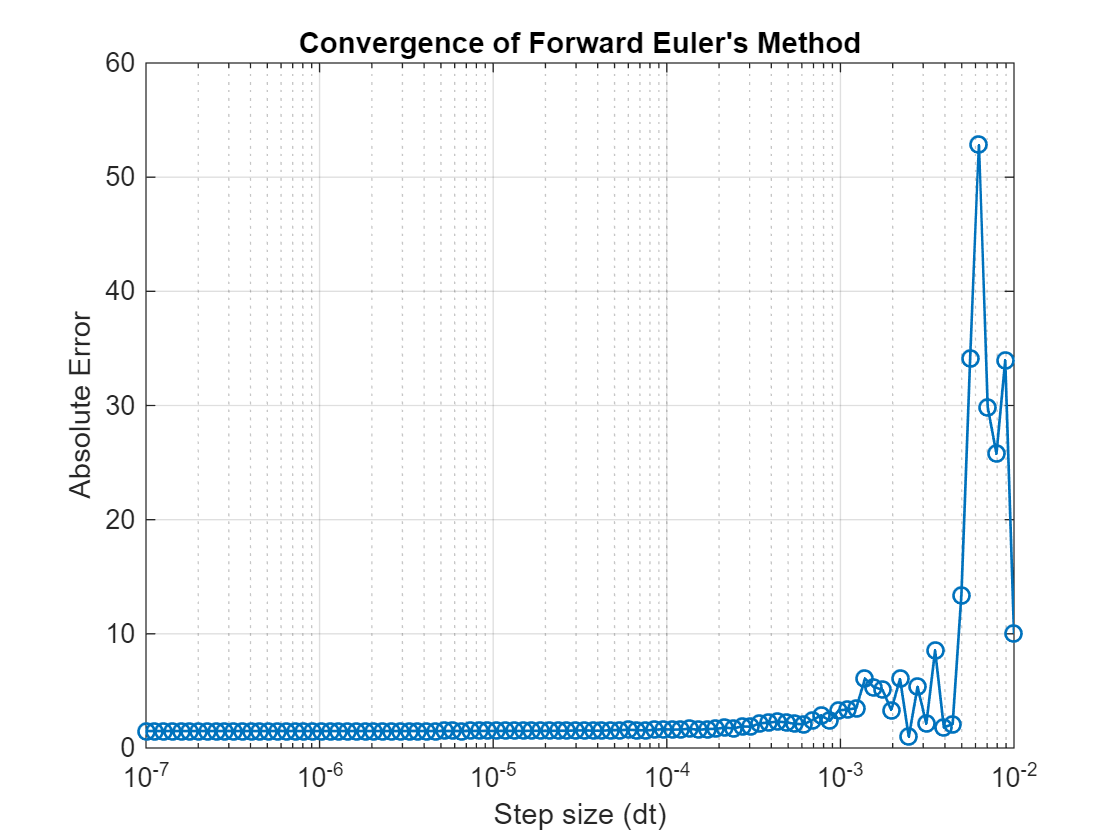

% Building log axis for dt
dt_val = logspace(-7,-2,100);

% Pre-allocation
errors = zeros(1, length(dt_val));

% Using ode45 as "real solution"
odefun = @(t, Psa) (Qtriangwave(t, Qmax, T, ts, tmax) - Psa./Rs)./Csa;
[t_ref, Psa_ref] = ode45(odefun, [0 25*T], 100);

% Loop over different step sizes
for ii = 1:length(dt_val)
    dt = dt_val(ii);
    t = 0:dt:25*T;

    % Preallocate solution 
    Psa_dt = zeros(1, length(t));
    Psa_dt(1)=100;

    % Forward Euler Method
    for jj = 1:length(t)-1
        QAo(jj)=Qtriangwave(t(jj),Qmax,T,ts,tmax);
        Psa_dt(jj+1) = Psa_dt(jj) + dt * (QAo(jj)-Psa_dt(jj)/Rs)/Csa;
    end

    % Absolute error at t = 2 forwards method
    errors(ii) = abs(Psa_ref(end) - Psa_dt(end));

end

% Plot convergence
figure
semilogx(dt_val, errors, '-o', 'LineWidth', 1);
grid on;
xlabel('Step size (dt)');
ylabel('Absolute Error');
title("Convergence of Forward Euler's Method");

## QUESTION 3: Exercise with an Abnormal Heart Rate Response

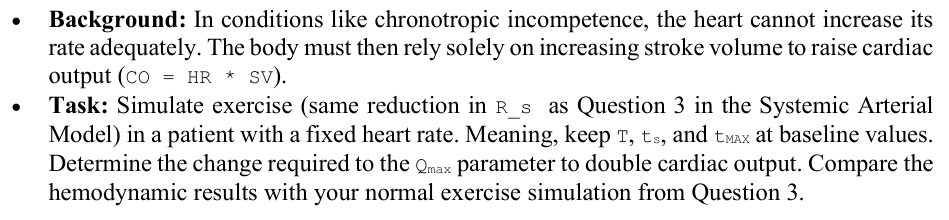

% Initial Parameters + Preallocating

% Baseline values
T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 10e-4; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 

% Abnormal heart
Rs_ah = Rs/2; % Same reduction as Q2 
Qmax_ah=2*Qmax; % New Qmax to get double CO
 

Psa_ah=zeros(length(t),1); Psa_ah(1)=100; % Pressure in systemic arteries (mmHg)
Vsa_ah=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs_ah=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao_ah=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

% New hemodynamics 
for k=1:length(t)-1 
    Qao_ah(k)=Qtriangwave(t(k),Qmax_ah,T,ts,tmax);  % Aortic Flow 
    Qs_ah(k)=Psa_ah(k)/Rs_ah; % Systemic Flow, assuming Psv<<Psa
    Psa_ah(k+1)=Psa_ah(k)+dt*(Qao_ah(k)-Qs_ah(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa_ah(k)=Csa*Psa_ah(k); % Volume in Systemic Arteries
end 

% Comparing results
CO_normal=mean(Qao_ex)*80;
CO_abnormal=mean(Qao_ah)*80;
fprintf('CO for normal heart = %.2f\n CO for abnormal heart = %.2f',CO_normal,CO_abnormal);

CO for normal heart = 226.60
 CO for abnormal heart = 453.21

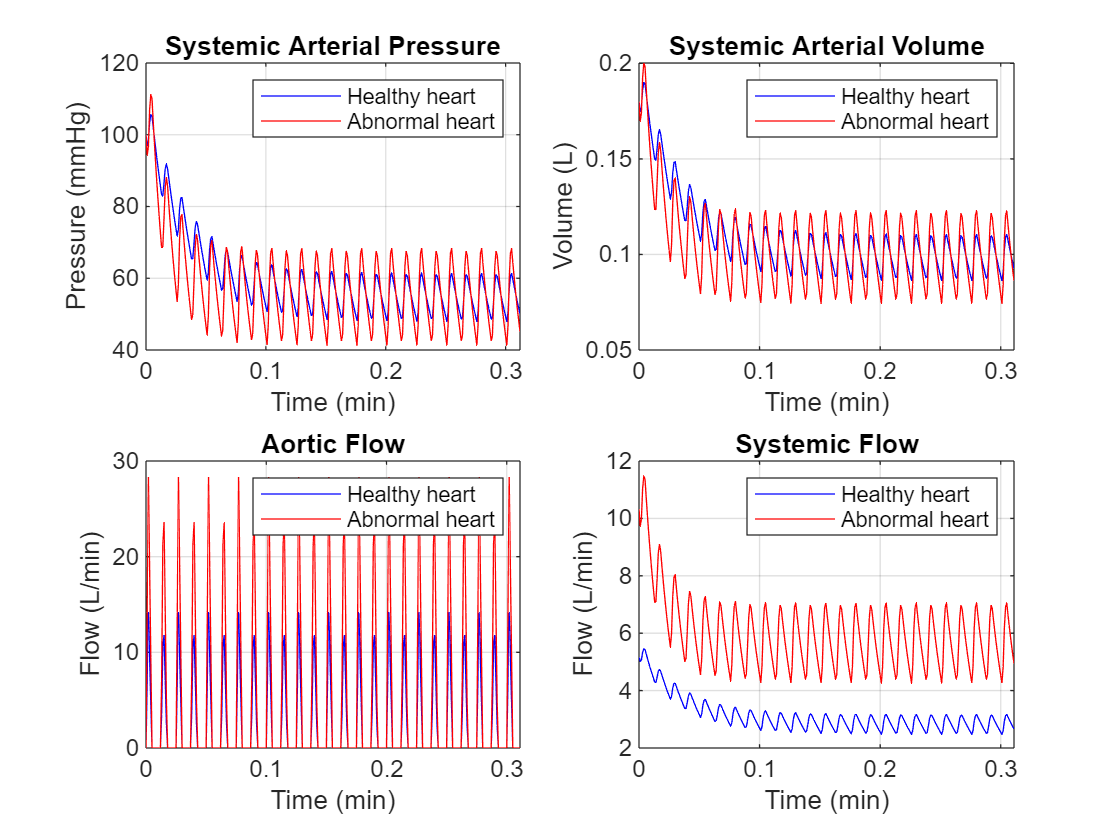

figure('Position',[100 100 1000 600]);
sgtitle('Abnormal Response to Exercise');

figure
subplot(2,2,1);
plot(t,Psa,'b',t,Psa_ah,'r');
xlabel('Time (min)'); 
ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure'); 
grid on; 
legend('Healthy heart','Abnormal heart');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b',t(1:end-1),Vsa_ah,'r');
xlabel('Time (min)'); 
ylabel('Volume (L)');
title('Systemic Arterial Volume'); 
grid on; 
legend('Healthy heart','Abnormal heart');

subplot(2,2,3);
plot(t(1:end-1),Qao,'b',t(1:end-1),Qao_ah,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Aortic Flow'); 
grid on; 
legend('Healthy heart','Abnormal heart');

subplot(2,2,4);
plot(t(1:end-1),Qs,'b',t(1:end-1),Qs_ah,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Systemic Flow'); 
grid on; 
legend('Healthy heart','Abnormal heart');

## QUESTION 4: Tachycardia in the Absence of Metabolic Demand 

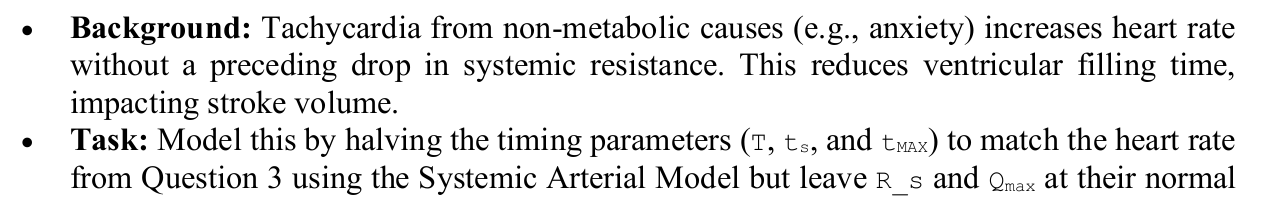

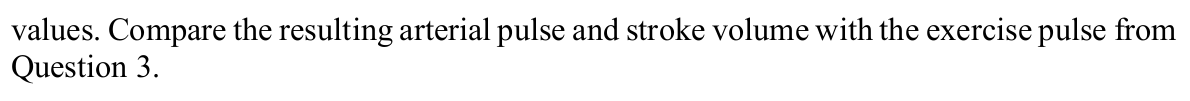

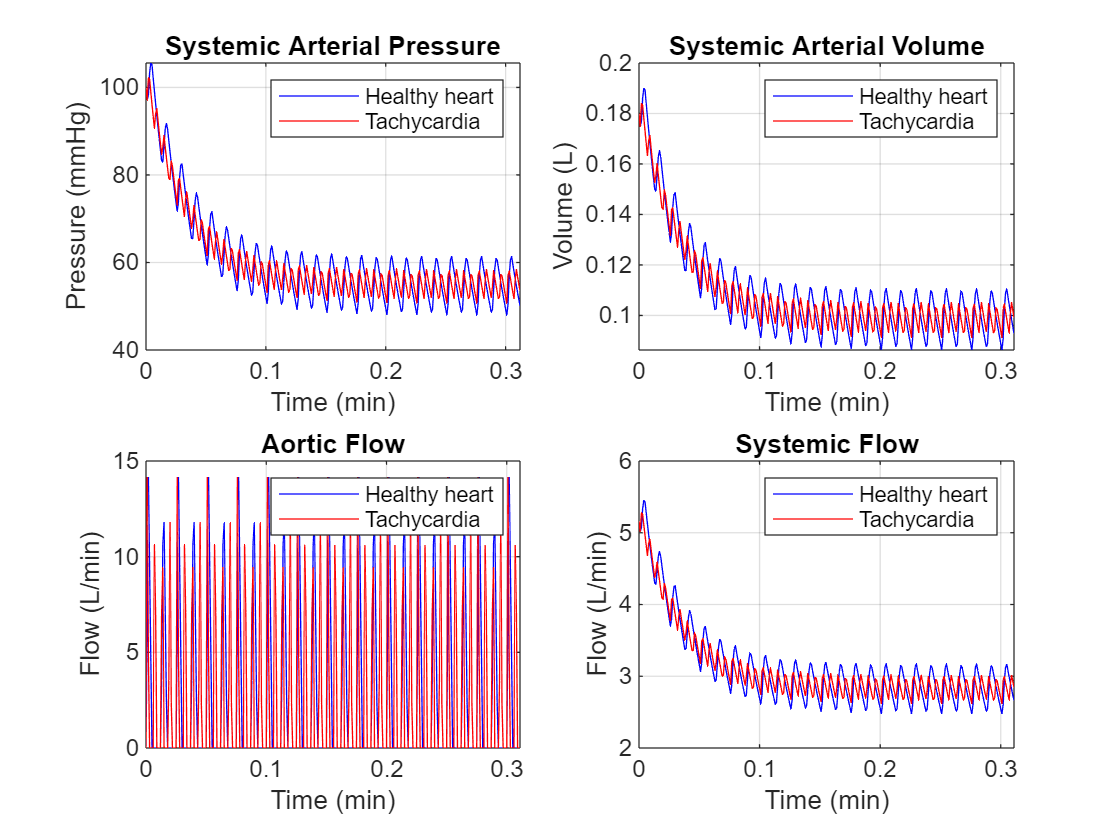

% Initial Parameters + Preallocating

% Baseline values
T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 10e-4; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 
Rs  = 17.5*1.107; % Resistance of the systemic circuit (mmHg/(L/min)) 
Qmax=14.14; % Max flow rate through aorta during systole (L/min) 

% Tachycardia (t values / 2)
T_t=T/2; 
ts_t=ts/2;
tmax_t=tmax/2;
 
Psa_t=zeros(length(t),1); Psa_t(1)=100; % Pressure in systemic arteries (mmHg)
Vsa_t=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs_t=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao_t=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

% New hemodynamics 
for k=1:length(t)-1 
    Qao_t(k)=Qtriangwave(t(k),Qmax,T_t,ts_t,tmax_t);  % Aortic Flow 
    Qs_t(k)=Psa_t(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa_t(k+1)=Psa_t(k)+dt*(Qao_t(k)-Qs_t(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa_t(k)=Csa*Psa_t(k); % Volume in Systemic Arteries
end 

% Comparing results
figure
subplot(2,2,1);
plot(t,Psa,'b',t,Psa_t,'r');
xlabel('Time (min)'); 
ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure'); 
grid on; 
legend('Healthy heart','Tachycardia');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b',t(1:end-1),Vsa_t,'r');
xlabel('Time (min)'); 
ylabel('Volume (L)');
title('Systemic Arterial Volume'); 
grid on; 
legend('Healthy heart','Tachycardia');

subplot(2,2,3);
plot(t(1:end-1),Qao,'b',t(1:end-1),Qao_t,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Aortic Flow'); 
grid on; 
legend('Healthy heart','Tachycardia');

subplot(2,2,4);
plot(t(1:end-1),Qs,'b',t(1:end-1),Qs_t,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Systemic Flow'); 
grid on; 
legend('Healthy heart','Tachycardia');

## QUESTION 5: Modeling a Myocardial Infarction

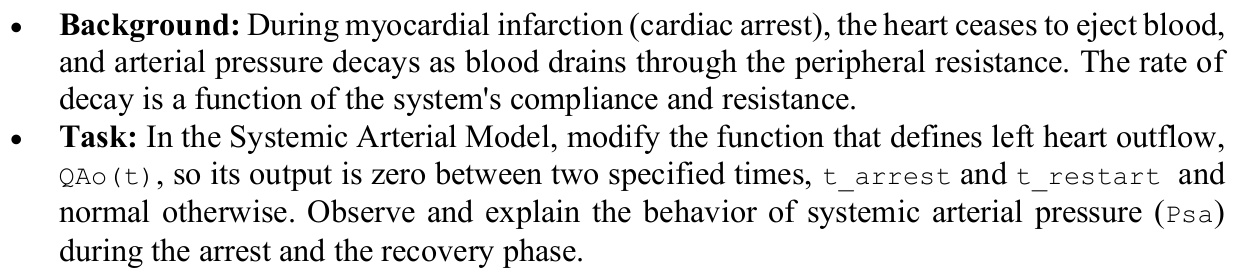

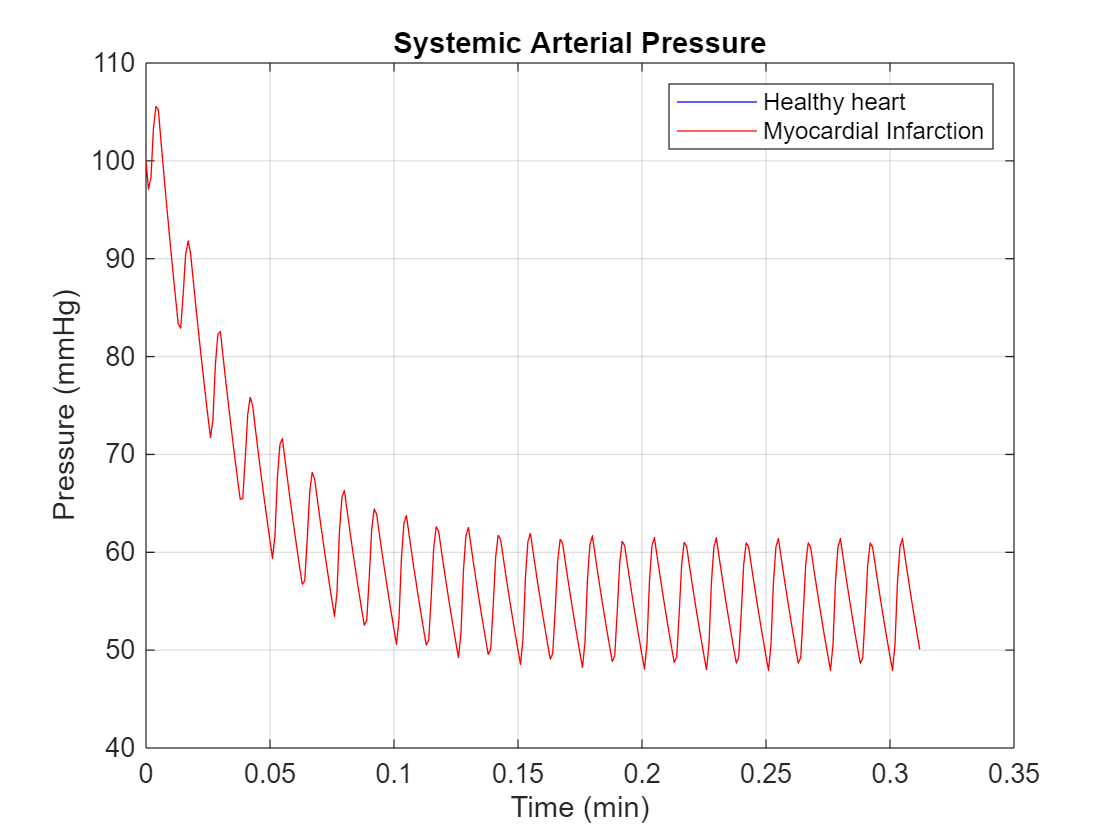

% New function for Qao
function Q=Qnew(t,Qmax,T,ts,tmax,t_arrest,t_restart)
% Same function as before but Q=0 if t is between t_arrest and t_restart
t1=rem(t,T);
    for ii=1:length(t)
        if t1>=t_arrest && t1<t_restart
            Q(ii)=0;
        else
            if t1(ii)<=ts 
                if t1(ii)<=tmax 
                    Q(ii)=Qmax*t1(ii)/tmax;
                else 
                    Q(ii)=Qmax*(ts-t1(ii))/(ts-tmax);
                end
            else % 
                Q(ii)=0;
            end
        end
    end
end 

% Baseline values
T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 10e-4; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 
Rs  = 17.5*1.107; % Resistance of the systemic circuit (mmHg/(L/min)) 
Qmax=14.14; % Max flow rate through aorta during systole (L/min) 
 
Psa_mi=zeros(length(t),1); Psa_mi(1)=100; % Pressure in systemic arteries (mmHg)
Vsa_mi=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs_mi=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao_mi=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

% Assigning values to t_arrest & t_restart
t_arrest=5*T;
t_restart=10*T;

% New hemodynamics 
for k=1:length(t)-1 
    Qao_mi(k)=Qnew(t(k),Qmax,T,ts,tmax,t_arrest,t_restart);  % Aortic Flow 
    Qs_mi(k)=Psa_mi(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa_mi(k+1)=Psa_mi(k)+dt*(Qao_mi(k)-Qs_mi(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa_mi(k)=Csa*Psa_mi(k); % Volume in Systemic Arteries
end 

% Comparing results
figure
plot(t,Psa,'b',t,Psa_mi,'r');
xlabel('Time (min)'); 
ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure'); 
grid on; 
legend('Healthy heart','Myocardial Infarction');

### VALVES

% State of valves -> open (1) or closed (0)

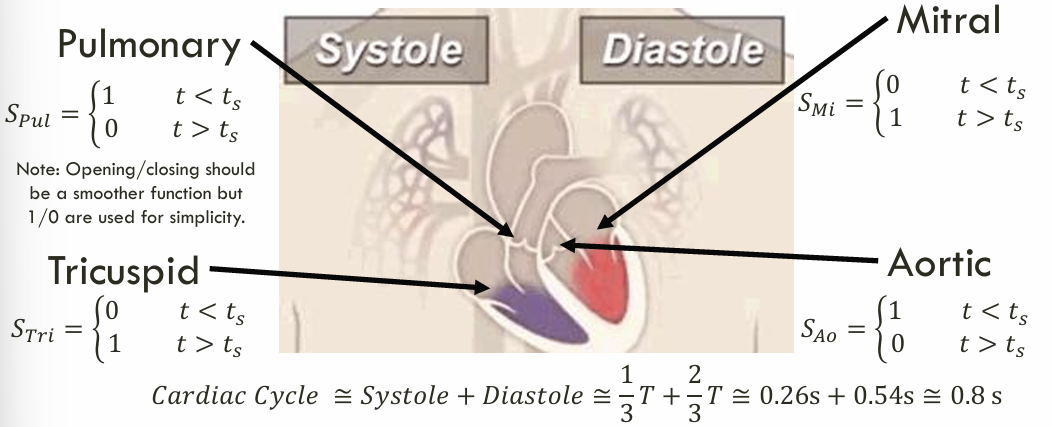

Initial parameters:

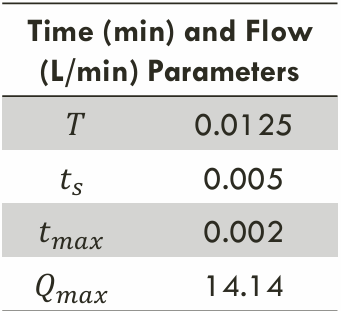

% Initial parameters
ts=0.005;
T=0.0125;
tspan=0:0.0001:2*T; % A smaller step gives better results

% I need these functions to be cyclic
tau = @(t) rem(t, T);   % This =0 every multiple of T so it restarts every cycle
u = @(t) double(tau(t) > ts);  % If t>T/3 Systole->Diastole : u=1 , If t>T and t<T/3 Diastole->Systole

% Systole -> AO + PUL open, MI + TRI closed
Spul=@(t) 1-u(t);
Sao=@(t) 1-u(t);

% Diastole -> AO + PUL closed, MI + TRI open
Stri=@(t) u(t);
Smi=@(t) u(t);

% Plotting to check
plot(tspan,Spul(tspan),'-r','LineWidth',1);
hold on
plot(tspan,Sao(tspan),'--r','LineWidth',2);
plot(tspan,Stri(tspan),'b','LineWidth',1);
plot(tspan,Smi(tspan),'--b','LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('State of valve');
title('Valves during the cardiac cycle');
legend('Pulmonary','Aortic','Tricuspid','Mitral','Location','bestoutside');
hold off

## Probando

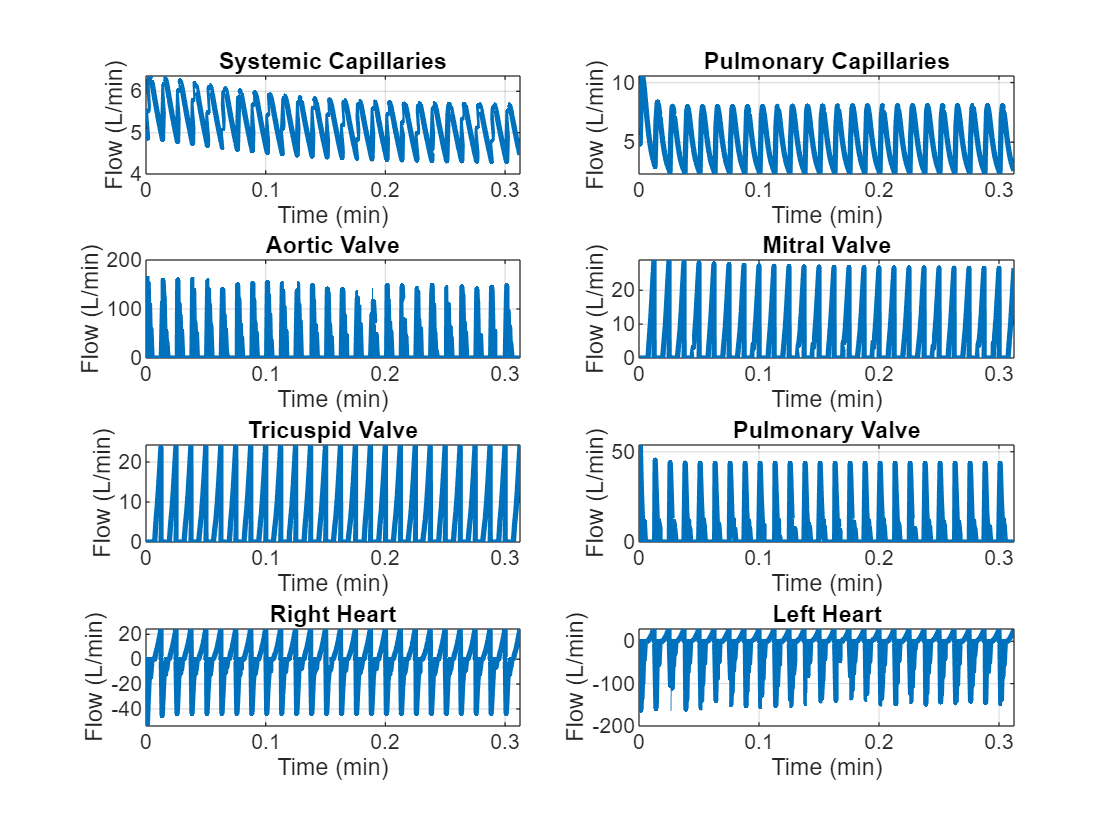

clear; clc; close all;

%% Systemic Arteries -> Systemic Veins -> Right Heart -> Pulmonary Arteries -> Pulmonary Veins -> Left Heart ->  start over

%% INITIAL PARAMETERS

% Time-related parameters (min)
T = 0.0125; % Heart period → 80 bpm
ts = 0.005; % Systole duration
dt = 10e-4; % Time step
t = 0:dt:25*T; % Simulate 25+ beats
tauS=0.0025; % Systolic time constant
tauD=0.0075; % Diastolic time constant

% Compliance (L/mmHg)
Csa = 0.0015*1.2; % Compliance constant for systemic arteries 
Csv=1.75; % Compliance constant for systemic veins
Cpa=0.004; % Compliance constant for pulmonary arteries
Cpv=0.08; % Compliance constant for pulmonary veins 
CRVS=0.0002; % RV systolic compliance 
CRVD=0.0365; % RV diastolic compliance 
CLVS = 0.00003; % LV systolic compliance 
CLVD = 0.0146; % LV diastolic compliance 

% Resistance (mmHg/(L/min)) 
Rs  = 17.5*1.107; % Systemic vascular resistance
Rp= 1.79; % Pulmonary vascular resistance
Rti=0.01; % Tricuspid valve resistance 
Rpo=0.01; % Pulmonary valve resistance
Rmi = 0.01; % Mitral valve resistance
Rao = 0.01; % Aortic valve resistance

%% PREALLOCATING

% Pressures (mmHg)
Psa=zeros(length(t),1); Psa(1)=100; % Pressure in systemic arteries
Psv=zeros(length(t),1); Psv(1)=2; % Pressure in systemic veins 
Ppa=zeros(length(t),1); Ppa(1)=15; % Pressure in pulmonary arteries 
Ppv=zeros(length(t),1); Ppv(1)=5; % Pressure in pulmonary veins 
Prv=zeros(length(t),1); Prv(1)=2; % Right ventricular pressure
Plv=zeros(length(t),1); Plv(1)=5; % Left ventricular pressure

% Volumes (L)
Vsa=zeros(length(t)-1,1); Vsa(1)=1; % Volume in systemic arteries
Vsv=zeros(length(t)-1,1); Vsv(1)=3.5; % Volume in the systemic veins
Vpa=zeros(length(t)-1,1); Vpa(1)=0.1; % Volume in the pulmonary arteries
Vpv=zeros(length(t)-1,1); Vpv(1)=0.4; % Volume in the pulmonary veins
Vrv=zeros(length(t),1); % Right ventricular volume 
Vlv=zeros(length(t),1); % Left ventricular volume

% Flows (L/min)
Qs=zeros(length(t)-1,1); % Systemic Capillaries Flow  
Qp=zeros(length(t)-1,1); % Pulmonary Capillaries Flow
Qtri=zeros(length(t)-1,1); % Tricuspid inflow
Qpul=zeros(length(t)-1,1); % Pulmonic outflow
Qr=zeros(length(t)-1,1); % Flow in the right heart (in - out)
Qmi=zeros(length(t)-1,1); % Mitral inflow
Qao=zeros(length(t)-1,1); % Aortic outflow
Ql=zeros(length(t)-1,1); % Flow in the left heart (in - out)

% Pressure-driven valve function
valve_open = @(P1, P2) P1 > P2;

% General Equation Form for Vascular Pressures
dP_dt=@(Q1,Q2,C) (Q1-Q2)/C;

%% GIANT LOOP
for k=1:length(t)-1 

    % Current and next compliance
    Crv_now  = CV_now(t(k),T,ts,tauS,tauD,CRVS,CRVD); % R for right heart
    Crv_next = CV_now(t(k+1),T,ts,tauS,tauD,CRVS,CRVD);
    Clv_now = CV_now(t(k),T,ts,tauS,tauD,CLVS,CLVD); % L for left heart
    Clv_next = CV_now(t(k+1),T,ts,tauS,tauD,CLVS,CLVD);

    % Valves were modeled based on pressure differences to make it more realistic
    S_ti = valve_open(Psv(k), Prv(k)); % Tricuspid: open if P_sv (representing RA) > P_RV
    S_po = valve_open(Prv(k), Ppa(k)); % Pulmonic:  open if P_RV > P_pa
    S_mi = valve_open(Ppv(k), Plv(k)); % Mitral: open if P_pv (representing LA) > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa

    % FLOWS
    Qs(k)=(Psa(k)-Psv(k))/Rs; % Systemic Capillaries Flow  
    Qp(k)=(Ppa(k)-Ppv(k))/Rp; % Pulmonary Capillaries Flow

    Qtri(k) = S_ti .* (Psv(k)   - Prv(k)) / Rti;  % Tricuspid inflow
    Qpul(k) = S_po .* (Prv(k) - Ppa(k)) / Rpo;  % Pulmonic outflow
    Qr(k)=Qtri(k)-Qpul(k); % Flow in the right heart (in - out)

    Qmi(k) = S_mi * (Ppv(k) - Plv(k)) / Rmi; % Mitral inflow
    Qao(k) = S_ao * (Plv(k) - Psa(k)) / Rao; % Aortic outflow
    Ql(k)=Qmi(k)-Qao(k); % Flow in the left heart (in - out)

    % PRESSURES RV & LV (with time-varying compliances)
    Prv(k+1) = (Prv(k) .* Crv_now + dt .* (Qtri(k) - Qpul(k))) / Crv_next; % Pressure in right ventricle
    Plv(k+1) = (Plv(k) .* Clv_now + dt * (Qmi(k) - Qao(k))) / Clv_next; % Pressure in left ventricle

    % VASCULAR PRESSURES
    Psa(k+1) = Psa(k) + dt * dP_dt(Qao(k),Qs(k),Csa); % Pressure in systemic arteries
    Psv(k+1) = Psv(k) + dt * dP_dt(Qs(k),Qtri(k),Csv); % Pressure in systemic veins 
    Ppa(k+1) = Ppa(k) + dt * dP_dt(Qpul(k),Qp(k),Cpa); % Pressure in pulmonary arteries
    Ppv(k+1) = Ppv(k) + dt * dP_dt(Qp(k),Qmi(k),Cpv); % Pressure in pulmonary veins
    
    % VOLUMES RV & LV
    Vrv(k+1) = Prv(k+1) .* Crv_next; % Volume in right ventricle
    Vlv(k+1) = Plv(k+1) .* Clv_next; % Volume in left ventricle

    %% VASCULAR VOLUMES
    Vsa(k+1)=Csa*Psa(k+1); % Volume in systemic arteries
    Vsv(k+1)=Csv*Psv(k+1); % Volume in systemic veins
    Vpa(k+1)=Cpa*Ppa(k+1); % Volume in Pulmonary Arteries
    Vpv(k+1)=Cpv*Ppv(k+1); % Volume in Pulmonary Veins

end 

%% PLOTTING

% Flows
figure
subplot(4,2,1)
plot(t(1:end-1),Qs,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Systemic Capillaries');

subplot(4,2,2)
plot(t(1:end-1),Qp,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Pulmonary Capillaries');

subplot(4,2,3)
plot(t(1:end-1),Qao,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Aortic Valve');

subplot(4,2,4)
plot(t(1:end-1),Qmi,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Mitral Valve');

subplot(4,2,5)
plot(t(1:end-1),Qtri,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Tricuspid Valve');

subplot(4,2,6)
plot(t(1:end-1),Qpul,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Pulmonary Valve');

subplot(4,2,7)
plot(t(1:end-1),Qr,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Right Heart');

subplot(4,2,8)
plot(t(1:end-1),Ql,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Left Heart');

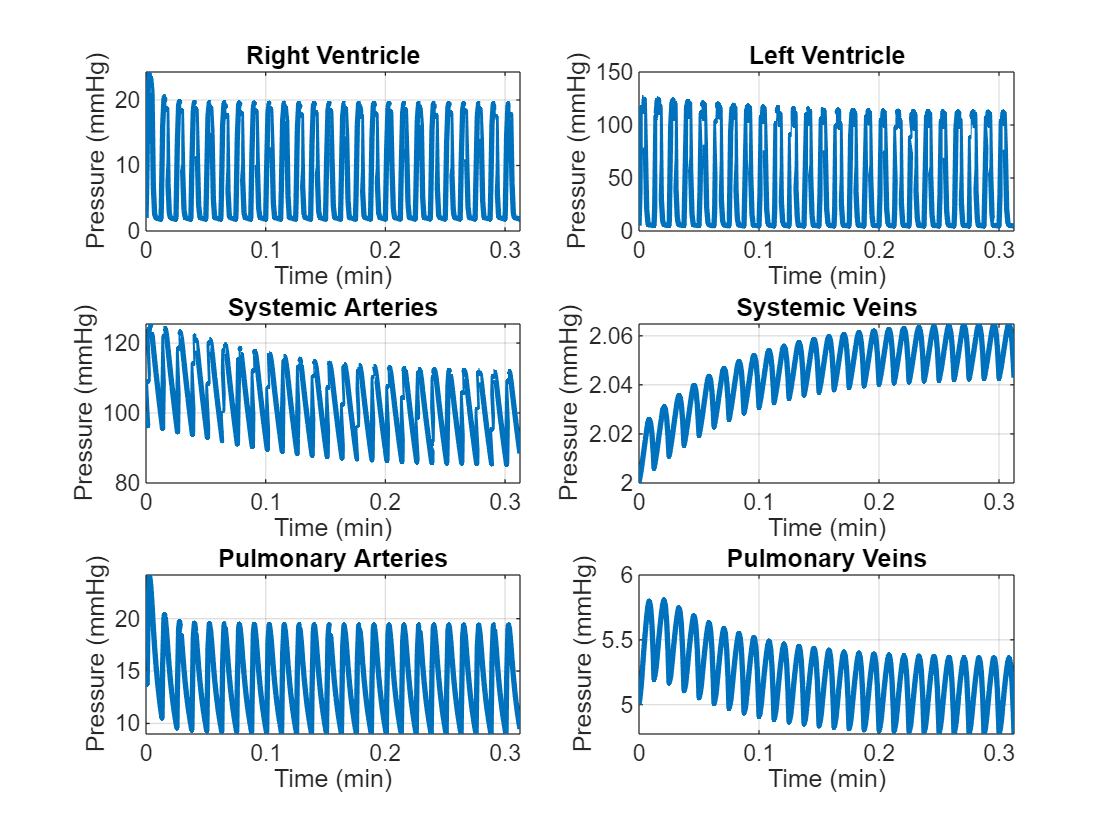

% f=gcf;
% exportgraphics(f,'Flows_Full.png','Resolution',600)

% Pressures
figure
subplot(3,2,1)
plot(t,Prv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Right Ventricle');

subplot(3,2,2)
plot(t,Plv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Left Ventricle');

subplot(3,2,3)
plot(t,Psa,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Systemic Arteries');

subplot(3,2,4)
plot(t,Psv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Systemic Veins');

subplot(3,2,5)
plot(t,Ppa,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Pulmonary Arteries');

subplot(3,2,6)
plot(t,Ppv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Pulmonary Veins');

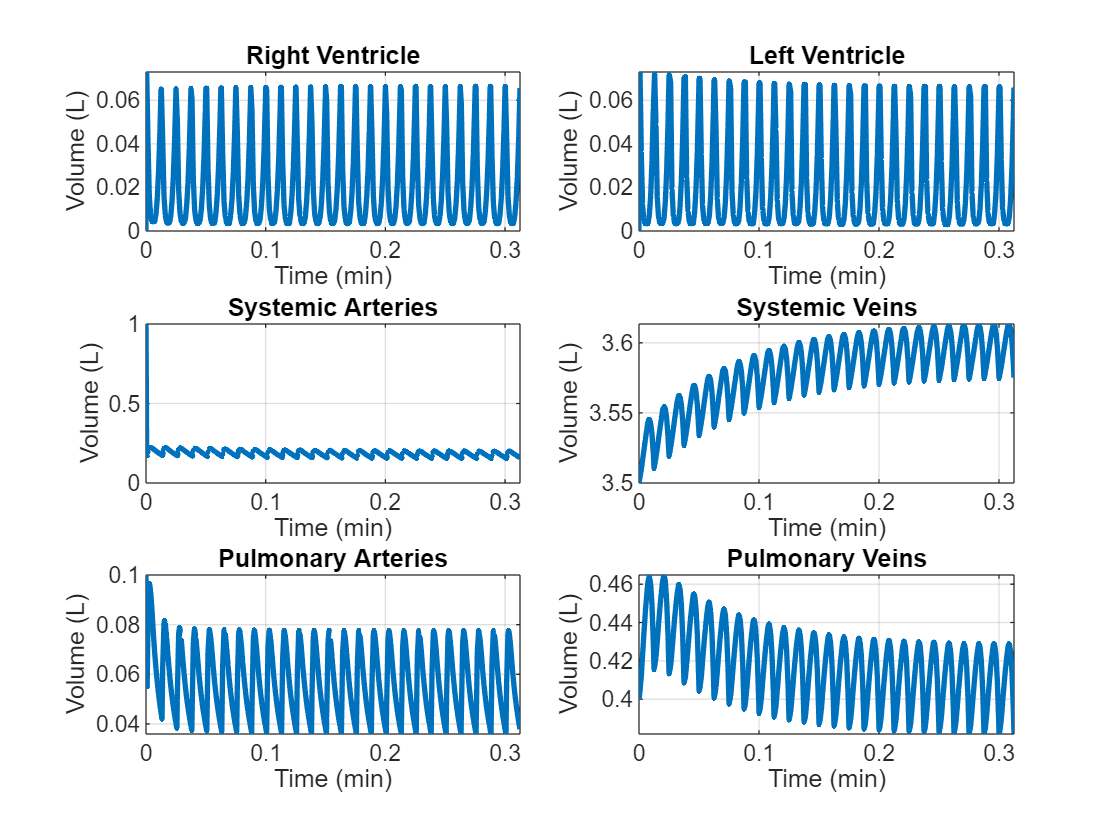

% Volumes
figure
subplot(3,2,1)
plot(t,Vrv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Right Ventricle');

subplot(3,2,2)
plot(t,Vlv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Left Ventricle');

subplot(3,2,3)
plot(t,Vsa,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Systemic Arteries');

subplot(3,2,4)
plot(t,Vsv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Systemic Veins');

subplot(3,2,5)
plot(t,Vpa,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Pulmonary Arteries');

subplot(3,2,6)
plot(t,Vpv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Pulmonary Veins');

## Testing timestep (LH)

### Left Heart Model 

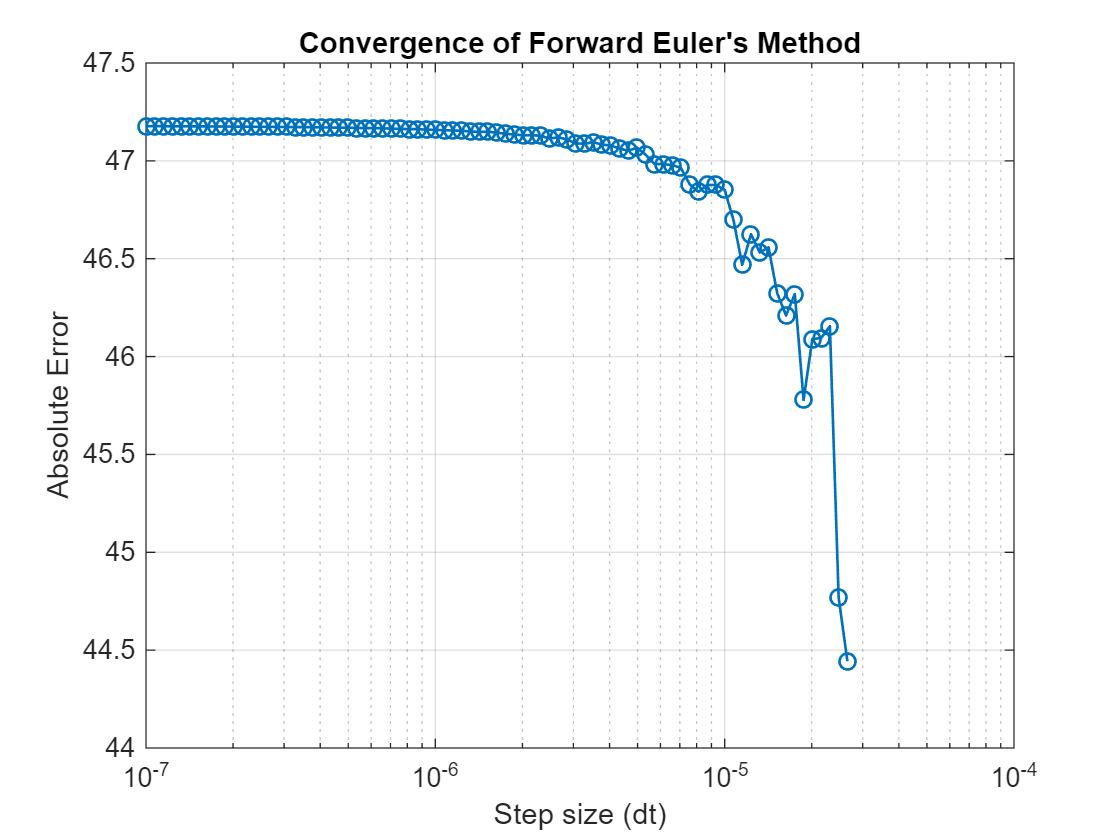

clear; clc; close all;

% PARAMETERS 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 10e-6; % Time step 
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

Rmi = 0.01; % Mitral resistance
Rao = 0.01; % Aortic resistance
Rs  = 17.5*1.107; % Systemic resistance
Csa = 0.0015*1.2; % Systemic arterial compliance
Ppv = 5; % Constant pulmonary venous pressure (left atrial proxy)

% INITIAL CONDITIONS

% PREALLOCATE
Psa = zeros(size(t)); Psa(1) = 100;
Plv = zeros(size(t)); Plv(1) = 5;
Vlv = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down); 

function CV=CV_now(t,T,ts,tauS,tauD,CVS,CVD)
% Compliance of the Ventricle Testing
% CVS and CVD refer to the compliance of either the right or left
% ventricle during systole and diastole, respectively. CLVS, CRVS,
% CLVD, and CRVD.
% Remainder of cardiac cycle
tc=rem(t,T);
    for ii=1:length(tc) % For every time point that’s in tc
        if tc(ii)<ts % If tc is less than ts, systole
             e=(1-exp(-tc(ii)/tauS))/(1-exp(-ts/tauS));
             CV(ii)=CVD*(CVS/CVD)^e;
        else % If tc is greater than ts, diastole
             e=(1-exp(-(tc(ii)-ts)/tauD))/(1-exp(-(T-ts)/tauD));
             CV(ii)=CVS*(CVD/CVS)^e;
        end
    end
end

% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now = CV_now(t(k),T,ts,tauS,tauD,CLVS,CLVD);
    Clv_next = CV_now(t(k)+dt,T,ts,tauS,tauD,CLVS,CLVD);
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv, Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows
    Qmi = S_mi * (Ppv - Plv(k)) / Rmi;
    Qao = S_ao * (Plv(k) - Psa(k)) / Rao;
    Qs  = Psa(k) / Rs; % Assuming Psv << Psa
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao - Qs) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi - Qao)) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

% Building log axis for dt
dt_val = logspace(-7,-4,100);

% Pre-allocation
errors = zeros(1, length(dt_val));

% Using ode45 as "real solution"
odefun = @(t, Psa) Psa + dt*(Qao - Qs) / Csa;
[t_ref, Psa_ref] = ode45(odefun, [0 25*T], 100);

% Loop over different step sizes
for ii = 1:length(dt_val)
    dt = dt_val(ii);
    t = 0:dt:25*T;

    % Preallocate solution 
    Psa_dt = zeros(1, length(t)); Psa_dt(1)=100;
    Plv = zeros(1, length(t)); Plv(1) = 5;
    Vlv = zeros(1, length(t));

    % Forward Euler Method
    for jj = 1:length(t)-1

        Clv_now = CV_now(t(jj),T,ts,tauS,tauD,CLVS,CLVD);
        Clv_next = CV_now(t(jj)+dt,T,ts,tauS,tauD,CLVS,CLVD);
        
        S_mi = valve_open(Ppv, Plv(jj));
        S_ao = valve_open(Plv(jj), Psa_dt(jj)); 

        Qmi = S_mi * (Ppv - Plv(jj)) / Rmi;
        Qao = S_ao * (Plv(jj) - Psa_dt(jj)) / Rao;
        Qs  = Psa_dt(jj) / Rs; 

        Plv(jj+1) = (Plv(jj) * Clv_now + dt * (Qmi - Qao)) / Clv_next;
        
        % Systemic arteries (normal ODE)
        dPsa_dt = (Qao - Qs) / Csa;
        Psa_dt(jj+1) = Psa_dt(jj) + dt * dPsa_dt;
        
    end

    % Absolute error at t = 2 forwards method
    errors(ii) = abs(Psa_ref(end) - Psa_dt(end));

end

% Plot convergence
figure
semilogx(dt_val, errors, '-o', 'LineWidth', 1);
grid on;
xlabel('Step size (dt)');
ylabel('Absolute Error');
title("Convergence of Forward Euler's Method");

% something is clearly wrong i need to fix it